clear;clc;close all
load('orbitdeterm_finalproj_KFdata.mat')

## Define Constants

mu = 3.986004418e5; %398800; % [km^3/s^2] Gravitational Constant
r0 = 6678; % [km] nominal orbit radius
w0 = sqrt(mu/r0^3);
% Constants for the output vector
Re = 6378; % [km]
we = 2*pi/86400; % [rad/s]
N = 12; % Number of ground stationss^2
dt = 10; % [s]
dtf = 0.1; % [s] fine dt
Tf = 14000; % [s] Final time (one orbit)
G = [0 0;1 0;0 0;0 1]; % Big omega matrix
O = dt*G;

## Nominal Trajectory

t = 0:dt:Tf;
t_fine = 0:dtf:Tf;
xnom = [r0*cos(w0*t);
    -r0*w0*sin(w0*t);
    r0*sin(w0*t);
    r0*w0*cos(w0*t)];

xnom(:,1) = [r0;0;0;r0*w0]+[0; 0.075; 0; -0.021];
for kk = 1:length(t_fine)-1
    % 4th order RK
     w = mvnrnd(zeros(1,2),Qtrue)';
    k1 = ([xnom(2,kk);
        -(mu*xnom(1,kk))/(xnom(1,kk)^2+xnom(3,kk)^2)^(3/2);
        xnom(4,kk);
        -(mu*xnom(3,kk))/(xnom(1,kk)^2+xnom(3,kk)^2)^(3/2)]);
    k2 = ([xnom(2,kk) + dtf*k1(2)/2;
        -(mu*xnom(1,kk)+dtf*k1(1)/2)/((xnom(1,kk) + dtf*k1(1)/2)^2+(xnom(3,kk)+dtf*k1(3)/2)^2)^(3/2);
        xnom(4,kk)+ dtf*k1(4)/2;
        -(mu*(xnom(3,kk)+dtf*k1(3)/2))/((xnom(1,kk) + dtf*k1(1)/2)^2+(xnom(3,kk)+dtf*k1(3)/2)^2)^(3/2)]);
    k3 = ([xnom(2,kk) + dtf*k2(2)/2;
        -(mu*xnom(1,kk)+dtf*k2(1)/2)/((xnom(1,kk) + dtf*k2(1)/2)^2+(xnom(3,kk)+dtf*k2(3)/2)^2)^(3/2);
        xnom(4,kk)+ dtf*k2(4)/2;
        -(mu*(xnom(3,kk)+dtf*k2(3)/2))/((xnom(1,kk) + dtf*k2(1)/2)^2+(xnom(3,kk)+dtf*k2(3)/2)^2)^(3/2)]);
    k4 = ([xnom(2,kk) + dtf*k3(2);
        -(mu*xnom(1,kk)+dtf*k3(1))/((xnom(1,kk) + dtf*k3(1))^2+(xnom(3,kk)+dtf*k3(3))^2)^(3/2);
        xnom(4,kk)+ dtf*k3(4);
        -(mu*(xnom(3,kk)+dtf*k3(3)))/((xnom(1,kk) + dtf*k3(1))^2+(xnom(3,kk)+dtf*k3(3))^2)^(3/2)]);
    xnom(:,kk+1) = xnom(:,kk) + 1/6*(k1+2*k2+2*k3+k4)*dtf;
end


% Downsample xnom
xnom_down = xnom(:,1);
for kk = 1:length(t)-1
    idx = (kk)*(dt/dtf);
    xnom_down(:,kk+1) = xnom(:,idx);
end

xnom = xnom_down;

## Linearized Perturbation

dxL(:,1) = [0; 0; 0; 0]; % Initial state perturbation

for kk = 1:length(t)-1
    dxL(:,kk+1) = (eye(4) + dt*A(xnom(:,kk),mu))*dxL(:,kk);
end
xLin = xnom+dxL; % Linear trajectory is nominal trajectory + perturbation

## Non-Linear States (With Noise)

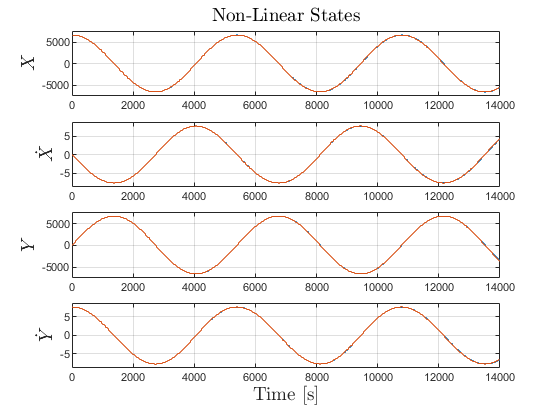

opts = odeset('RelTol',1e-12,'AbsTol',1e-5);
[~,xNL2] = ode45(@nLEQ,t,[r0;0;0;r0*w0]+[0; 0.075; 0; -0.021],opts);
xNL2 = xNL2';

xNL(:,1) = [r0;0;0;r0*w0]+[0; 0.075; 0; -0.021];
for kk = 1:length(t_fine)-1
    % 4th order RK
     w = mvnrnd(zeros(1,2),Qtrue)';
    k1 = ([xNL(2,kk);
        -(mu*xNL(1,kk))/(xNL(1,kk)^2+xNL(3,kk)^2)^(3/2);
        xNL(4,kk);
        -(mu*xNL(3,kk))/(xNL(1,kk)^2+xNL(3,kk)^2)^(3/2)]) + G*w;
    k2 = ([xNL(2,kk) + dtf*k1(2)/2;
        -(mu*xNL(1,kk)+dtf*k1(1)/2)/((xNL(1,kk) + dtf*k1(1)/2)^2+(xNL(3,kk)+dtf*k1(3)/2)^2)^(3/2);
        xNL(4,kk)+ dtf*k1(4)/2;
        -(mu*(xNL(3,kk)+dtf*k1(3)/2))/((xNL(1,kk) + dtf*k1(1)/2)^2+(xNL(3,kk)+dtf*k1(3)/2)^2)^(3/2)]) + G*w;
    k3 = ([xNL(2,kk) + dtf*k2(2)/2;
        -(mu*xNL(1,kk)+dtf*k2(1)/2)/((xNL(1,kk) + dtf*k2(1)/2)^2+(xNL(3,kk)+dtf*k2(3)/2)^2)^(3/2);
        xNL(4,kk)+ dtf*k2(4)/2;
        -(mu*(xNL(3,kk)+dtf*k2(3)/2))/((xNL(1,kk) + dtf*k2(1)/2)^2+(xNL(3,kk)+dtf*k2(3)/2)^2)^(3/2)]) + G*w;
    k4 = ([xNL(2,kk) + dtf*k3(2);
        -(mu*xNL(1,kk)+dtf*k3(1))/((xNL(1,kk) + dtf*k3(1))^2+(xNL(3,kk)+dtf*k3(3))^2)^(3/2);
        xNL(4,kk)+ dtf*k3(4);
        -(mu*(xNL(3,kk)+dtf*k3(3)))/((xNL(1,kk) + dtf*k3(1))^2+(xNL(3,kk)+dtf*k3(3))^2)^(3/2)]) + G*w;
    xNL(:,kk+1) = xNL(:,kk) + 1/6*(k1+2*k2+2*k3+k4)*dtf;
end


% Downsample xNL
xNL_down = xNL(:,1);
for kk = 1:length(t)-1
    idx = (kk)*(dt/dtf);
    xNL_down(:,kk+1) = xNL(:,idx);
end

xNL = xNL_down;

figure
ylabs = {'$X$','$\dot{X}$','$Y$','$\dot{Y}$'};
for kk = 1:4
    sb(kk) = subplot(4,1,kk);
    stairs(t,xNL(kk,:))
    hold on
    stairs(t,xNL2(kk,:))
    grid on
    ylabel(ylabs{kk},'Interpreter','Latex','FontSize',14)
    axis padded
    xlim([0 Tf])
end
xlabel('Time [s]','Interpreter','Latex','FontSize',14)
linkaxes(sb,'x')
subplot(4,1,1)
title('Non-Linear States','Interpreter','Latex','FontSize',14)

## Non-Linear Outptus (With Noise)

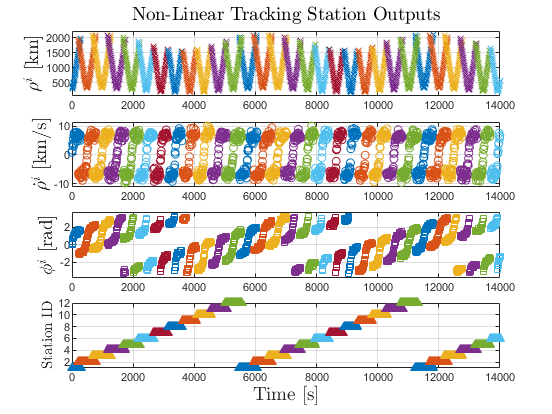

visSatsNL = diag(1:12)*ones(N,size(t,2));
for kk = 1:length(t)
    
    for nn = 1:12
        thi = wrapTo2Pi((nn - 1)*pi/6); % Theta 0 for ground station i
        Xis = Re*cos(we*t(kk)+thi);
        Yis = Re*sin(we*t(kk)+thi);
        dXis = -Re*we*sin(we*t(kk)+thi);
        dYis = Re*we*cos(we*t(kk)+thi);
        x_stat(:,kk,nn) = [Xis;dXis;Yis;dYis];

        thLim = we*t(kk)+thi;
        v = mvnrnd(zeros(1,3),Rtrue)';
        yNL(:,kk,nn) = [sqrt((xNL(1,kk)-Xis)^2+(xNL(3,kk)-Yis)^2);
                    ((xNL(1,kk)-Xis)*(xNL(2,kk)-dXis)+(xNL(3,kk)-Yis)*(xNL(4,kk)-dYis))/(sqrt((xNL(1,kk)-Xis)^2+(xNL(3,kk)-Yis)^2));
                    atan2((xNL(3,kk)-Yis),(xNL(1,kk)-Xis))];
        
        yNL_noisy(:,kk,nn) = yNL(:,kk,nn) + v;

        inView = and(angdiff(yNL(3,kk,nn),thLim) <= pi/2,angdiff(yNL(3,kk,nn),thLim) >= -pi/2);
        if ~inView
            yNL_noisy(:,kk,nn) = [NaN;NaN;NaN];
            yNL(:,kk,nn) = [NaN;NaN;NaN];
            visSatsNL(nn,kk) = NaN;
        end
    end
end

linType = {'x','o','square','^'};
ylabs = {'$\rho^i$ [km]','$\dot{\rho}^i$ [km/s]','$\phi^i$ [rad]','Station ID'};
figure
for kk = 1:3
    sb(kk) = subplot(4,1,kk);
    for nn = 1:12
        plot(t,yNL_noisy(kk,:,nn),linType{kk})
        hold on
    end
    ylabel(ylabs{kk},'Interpreter','Latex','FontSize',14)
    grid on
    hold off
    axis padded
    xlim([0 Tf])
end
sb(4) = subplot(4,1,4);
plot(t,visSatsNL,linType{4})
ylim([1 12])
grid on
ylabel(ylabs{4},'Interpreter','Latex','FontSize',11)
linkaxes(sb,'x')
xlabel('Time [s]','Interpreter','Latex','FontSize',14)
subplot(4,1,1)
title('Non-Linear Tracking Station Outputs','Interpreter','Latex','FontSize',14)

## Outputs and Ground Stations (Linear)

visSats = diag(1:12)*ones(N,size(t,2));
for kk = 1:length(t)
    for nn = 1:12
        thi = wrapTo2Pi((nn - 1)*pi/6); % Theta 0 for ground station i
        Xis = Re*cos(we*t(kk)+thi);
        Yis = Re*sin(we*t(kk)+thi);
        dXis = -Re*we*sin(we*t(kk)+thi);
        dYis = Re*we*cos(we*t(kk)+thi);
        x_stat(:,kk,nn) = [Xis;dXis;Yis;dYis];

        thLim = we*t(kk)+thi;
        
        ynom(:,kk,nn) = [sqrt((xnom(1,kk)-Xis)^2+(xnom(3,kk)-Yis)^2);
                    ((xnom(1,kk)-Xis)*(xnom(2,kk)-dXis)+(xnom(3,kk)-Yis)*(xnom(4,kk)-dYis))/(sqrt((xnom(1,kk)-Xis)^2+(xnom(3,kk)-Yis)^2));
                    atan2((xnom(3,kk)-Yis),(xnom(1,kk)-Xis))];

        dy(:,kk,nn) = C(xnom(:,kk),t(kk),nn)*dxL(:,kk); % Get measurement perturbation

        yLin(:,kk,nn) = ynom(:,kk,nn) + dy(:,kk,nn);

        inView = and(angdiff(yNL(3,kk,nn),thLim) <= pi/2,angdiff(yNL(3,kk,nn),thLim) >= -pi/2);
        if ~inView
            yLin(:,kk,nn) = [NaN;NaN;NaN];
            visSats(nn,kk) = NaN;
        end
    end
end

## Kalman Filtering

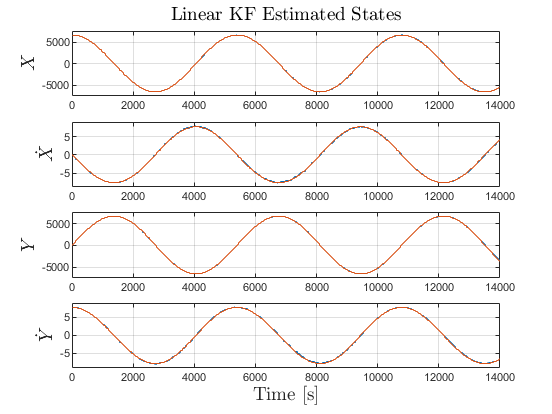



Qassumed = [
0.00712462310419587	0.00186609561266122*1e-5;
0.00186609561266122*1e-5	0.00779388288435167]*1e-2;
% Qassumed = [7.12462310419587e-05    1.86609561266122e-05;
% 1.86609561266122e-05    7.79388288435167e-05];
% Qassumed = [2e-10 1e-10;2e-10 1e-10]*1e4;

Rassumed = Rtrue*1;
Qt_diag = diag(Qassumed);
visSatsBool = ~isnan(visSatsNL);
numSats = sum(visSatsBool);
dx(:,1) = [0; 0; 0; 0]; % State estimate
dx_predict(:,1) = [0; 0.075; 0; -0.021]*0; % State prediction
P(:,:,1) = diag([1e-4 0.0056 1e-4 4.441e-4]);
% P(:,:,1) = rand(4,4);
P_predict(:,:,1) = eye(4);
for kk = 1:length(t)-1
    % Define matrices
    F = eye(4) + dt*A(xnom(:,kk),mu);
    satNums = visSatsNL(visSatsBool(:,kk+1),kk+1);
    H_kp1 = [];
    dy_kp1 = [];
    for ii = 1:numSats(kk+1)
        H_kp1 = [H_kp1; C(xnom(:,kk+1),t(kk+1),satNums(ii))];
        
        yMeasurement = yNL_noisy(:,kk+1,satNums(ii));
        yMeasurement(3) = wrapToPi(yMeasurement(3));

        yNominal = ynom(:,kk+1,satNums(ii));
        yNominal(3) = wrapToPi(yNominal(3));
        

        dynew = yMeasurement - yNominal;
        dynew(3) = wrapToPi(dynew(3));


        dy_kp1 = [dy_kp1 ; dynew];
    end
    Rused = kron(eye(numSats(kk+1)),Rassumed);
        % Prediction Step
        dx_predict(:,kk+1) = F*dx(:,1);
        P_predict(:,:,kk+1) = F*P(:,:,kk)*F' + O*Qassumed*O';


        if ~isempty(H_kp1)
        % Measurement Update
            K = P_predict(:,:,kk+1)*H_kp1'*inv(H_kp1*P_predict(:,:,kk+1)*H_kp1'+Rused);
            dx(:,kk+1) = dx_predict(:,kk+1) + K*(dy_kp1-H_kp1*dx_predict(:,kk+1));
            P(:,:,kk+1) = (eye(4) - K*H_kp1)*P_predict(:,:,kk+1);
        else
        % Just use prediction if no ground staions in view
            dx(:,kk+1) = dx_predict(:,kk+1);
            P(:,:,kk+1) = P_predict(:,:,kk+1);
        end
end


xLin = xnom + dx;
figure
ylabs = {'$X$','$\dot{X}$','$Y$','$\dot{Y}$'};
for kk = 1:4
    sb(kk) = subplot(4,1,kk);
    stairs(t,xLin(kk,:))
    hold on
    stairs(t,xNL2(kk,:))
    grid on
    ylabel(ylabs{kk},'Interpreter','Latex','FontSize',14)
    axis padded
    xlim([0 Tf])
end
xlabel('Time [s]','Interpreter','Latex','FontSize',14)
linkaxes(sb,'x')
subplot(4,1,1)
title('Linear KF Estimated States','Interpreter','Latex','FontSize',14)

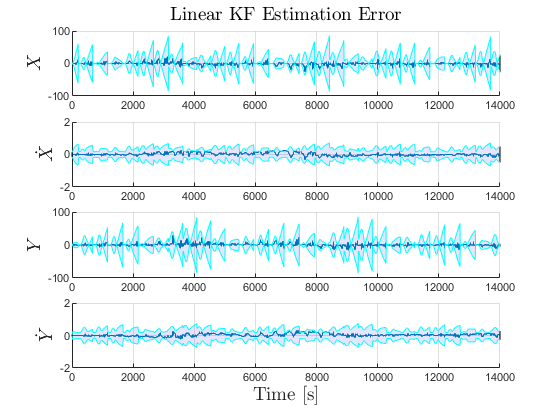



xE = dx - (xNL - xnom);
figure
ylabs = {'$X$','$\dot{X}$','$Y$','$\dot{Y}$'};
yLims = [100; 2; 100; 2];
for kk = 1:4
    sb(kk) = subplot(4,1,kk);
    patch([t fliplr(t)], [2*sqrt(squeeze(P(kk,kk,:))') fliplr(-2*sqrt(squeeze(P(kk,kk,:))'))], 'blue','FaceAlpha',.1)
    hold on
    stairs(t,xE(kk,:))
    plot(t,2*sqrt(squeeze(P(kk,kk,:))'),'c')
    plot(t,-2*sqrt(squeeze(P(kk,kk,:))'),'c')
    

    grid on
    ylabel(ylabs{kk},'Interpreter','Latex','FontSize',14)
    axis padded
    xlim([0 Tf])
    ylim([-yLims(kk) yLims(kk)])
end
xlabel('Time [s]','Interpreter','Latex','FontSize',14)
linkaxes(sb,'x')
subplot(4,1,1)
title('Linear KF Estimation Error','Interpreter','Latex','FontSize',14)